# Numerical Methods in Engineering

## Exercise 1

** Given the following 3rd order differential equation,**

                
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(\frac{\pi t} {4})$$


**a) The above differential equation is transformed into a system of first-order differential equations below. (5 marks)**


$$Y(t)=\left[
\matrix{
y_{1} \cr
y_{2} \cr
y_{3}
}
\right]
=
\left[
\matrix{
y \cr
\dot{y} \cr
\ddot{y}
}
\right]$$



$$\left[
\matrix{
\dot{y_{1}} \cr
\dot{y_{2}} \cr
\dot{y_{3}}
}
\right]
=
\left[
\matrix{
y_2 \cr
y_3 \cr
\sin\left(\frac{{\pi}t}{4}\right)-32y_3-61.25y_2-37.5y_1
}
\right]$$



$$I\dot{Y}(t)
=
\left[
\matrix{
0 & 1 & 0 \cr
0 & 0 & 1 \cr
-37.5 & -61.25 & -32 \cr
}
\right]
Y(t)+
\left[
\matrix{
0 \cr
0 \cr
\sin\left(\frac{{\pi}t}{4}\right)
}
\right]$$



$$I\dot{Y}(t) + 
\left[
\matrix{
0 & -1 & 0 \cr
0 & 0 & -1 \cr
37.5 & 61.25 & 32 \cr
}
\right]
Y(t)
=
\left[
\matrix{
0 \cr
0 \cr
\sin\left(\frac{{\pi}t}{4}\right)
}
\right]$$


**b)  For the system of first order ODEs obtained in part a), the Backward Euler approximation is applied for the derivative and the obtained difference equation is written below.** **(5 marks)**


$$I\dot{Y}(t) + 
\left[
\matrix{
0 & -1 & 0 \cr
0 & 0 & -1 \cr
37.5 & 61.25 & 32 \cr
}
\right]
Y(t)
=
\left[
\matrix{
0 \cr
0 \cr
\sin\left(\frac{{\pi}t}{4}\right)
}
\right]$$



$$C=I$$



$$G=\left[
\matrix{
0 & -1 & 0 \cr
0 & 0 & -1 \cr
37.5 & 61.25 & 32 \cr
}
\right]$$



$$b(t)=\left[
\matrix{
0 \cr
0 \cr
\sin\left(\frac{{\pi}t}{4}\right)
}
\right]$$



$$GY+C\dot{Y}=b(t)$$



$$Y_{n+1}=Y_n+h\dot{Y}_{n+1}$$



$$\dot{Y}=C^{-1}(b(t)-GY)$$


Since c is the identity matrix, its inverse is also the identity matrix:


$$\dot{Y}=b(t)-GY$$



$$Y_{n+1}=Y_n+h(b(t_{n+1})-GY_{n+1})$$



$$Y_{n+1}=Y_n+hb(t_{n+1})-hGY_{n+1}$$



$$Y_{n+1}+hGY_{n+1}=Y_n+hb(t_{n+1})$$



$$(I+hG)Y_{n+1}=Y_n+hb(t_{n+1})$$



$$Y_{n+1}=(I+hG)^{-1}(Y_n+hb(t_{n+1}))$$


**c) Given the initial conditions **$y(0) =0$**, **$y'(0) =1$**, and **$y''(0) = 0$** for the given differential equation, the cell below is used to implement the Backward Euler method to solve the first order ODE's obtained in part a) . The simulation is run for **$25s$** using the time step **$\Delta t= 0.065s$**. The**$y(t)$** vs **$t$** is plotted on the same graph as the true solution. (5 marks)**

clear all;
dT = 0.065; % seconds
T = 0:dT:25; 

%-----------------------------------------------------------------------------
Y = zeros(3,length(T));
C = eye(3);
G =[
0 -1 0
0 0 -1
37.5 61.25 32
];
b = [0;0;1];


Y(:,1)=[0;1;0];

for n = 2 : length(T)
    Y(:,n) = (C+dT*G)\(Y(:,n-1)+dT*sin(pi*T(n)/4)*b);
end

y = Y(1,:);

%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical solution for reference

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------

plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t)                   
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

**d)  Part c) code is ran again for **$25s$** using the time step **$\Delta t= 1s$**.  The **$y(t)$** vs **$t$** is plotted on the same graph  as the true solution. Making observations on if the obtained solution is more accurate than the solution in part c?** **(2 marks)**

clear all
dT = 1; % seconds
T = 0:dT:25; 

%-----------------------------------------------------------------------------

Y = zeros(3,length(T));
C = eye(3);
G =[
0 -1 0
0 0 -1
37.5 61.25 32
];
b = [0;0;1];


Y(:,1)=[0;1;0];

for n = 2 : length(T)
    Y(:,n) = (C+dT*G)\(Y(:,n-1)+dT*sin(pi*T(n)/4)*b);
end

y = Y(1,:);

%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical solution for reference
figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).                         
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*Because a bigger time step is used, the obtained solution becomes less accurate. *

**e) For the system of first-order ODEs obtained in part a), the Forward Euler approximation is used for the derivative. The obtained difference equation is written below.** **(5 marks)**


$$I\dot{Y}(t) + 
\left[
\matrix{
0 & -1 & 0 \cr
0 & 0 & -1 \cr
37.5 & 61.25 & 32 \cr
}
\right]
Y(t)
=
\left[
\matrix{
0 \cr
0 \cr
\sin\left(\frac{{\pi}t}{4}\right)
}
\right]$$



$$C=I$$



$$G=\left[
\matrix{
0 & -1 & 0 \cr
0 & 0 & -1 \cr
37.5 & 61.25 & 32 \cr
}
\right]$$



$$b(t)=\left[
\matrix{
0 \cr
0 \cr
\sin\left(\frac{{\pi}t}{4}\right)
}
\right]$$



$$GY+C\dot{Y}=b(t)$$



$$Y_{n+1}=Y_n+h\dot{Y}_{n}$$



$$\dot{Y}=C^{-1}(b(t)-GY)$$


Since c is the identity matrix, its inverse is also the identity matrix. 


$$\dot{Y}=b(t)-GY$$



$$Y_{n+1}=Y_n+h(b(t_n)-GY_n)$$


**f) Using the same initial conditions as part c) (i.e. **$y(0) =0$**, **$y'(0) =1$**, and **$y''(0) = 0$**), the Forward Euler method is implemented to solve the first order ODE's obtained in part a) . The simulation is run for **$25s$**, using the time step **$\Delta t= 0.065s$**. The**$y(t)$** vs **$t$** is plotted on the same graph as the true solution.** **(5 marks)**

clear all;
dT = 0.065; % seconds
T = 0:dT:25; 

%-----------------------------------------------------------------------------

Y = zeros(3,length(T));
G =[
0 -1 0
0 0 -1
37.5 61.25 32
];
b = [0;0;1];

Y(:,1)=[0;1;0];

for n = 2 : length(T)
    Y(:,n) = Y(:,n-1)+dT*(sin(pi*T(n-1)/4)*b-G*Y(:,n-1));
end

y = Y(1,:);

%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical solution for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Forward Euler')
% Note: the variable y is the y(t).                          
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

**e) The code written in part f) is ran again for **$25s$** but with a time step of **$\Delta t= 0.068s$**.  The **$y(t)$** vs **$t$** is plotted on the same graph as the true solution. A comment on the obtained solutions in part e) and f) is provided below.** **(2 marks)**

clear all
dT = 0.068; % seconds
T = 0:dT:25; 

%-----------------------------------------------------------------------------

Y = zeros(3,length(T));
C = eye(3);
G =[
0 -1 0
0 0 -1
37.5 61.25 32
];
b = [0;0;1];

Y(:,1)=[0;1;0];

for n = 2 : length(T)
    Y(:,n) = Y(:,n-1)+dT*(sin(pi*T(n-1)/4)*b-G*Y(:,n-1));
end

y = Y(1,:);

%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical solution for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).                            
%--------------------------------------------------------------------------------                                                              

ylim([-0.05 0.4])  
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*As can be observed by the different plot outputs for part f) vs. part e), the time steps used has a significant impact on the stability of the output for the Forward Euler solution computations. In part f), a time step of 0.065s resulted in a highly stable and generally accurate solution. In part e), a larger time step of 0.068s resulted in a highly unstable and inaccurate solution past around the 3rd second. *

**Sources used to complete this section:**

- [https://ky**leniemeyer.github.io/ME373-book/content/second-order/numerical-methods.html#:~:text=In%20general%2C%20we%20can%20use,recursion%20formula%20and%20solve%20for**](https://kyleniemeyer.github.io/ME373-book/content/second-order/numerical-methods.html#:~:text=In%20general%2C%20we%20can%20use,recursion%20formula%20and%20solve%20for)

- [**https://www.youtube.com/watch?v=irfSuY-Cmds**](https://www.youtube.com/watch?v=irfSuY-Cmds)

- https://www.youtube.com/watch?v=QuyBVdDHkZY

## Exercise 2:  

**a) The steepest descent algorithm is used to solve the linear system of equations given by **$\textbf A \textbf x = \textbf b$**, where **$\textbf A \in \mathbb{R}^{n \times n}$** is a symmetric and positive definite matrix, **$\textbf b \in \mathbb{R}^{n \times 1}$** and **$\textbf x \in \mathbb{R}^{n \times 1}$**.  (10 marks)**

*The algorithm is written in the appendix in the function named my_steepest_descent().*

**b)** **The *****my_steepest_descent() *****code is tested in the cell below.**

n = 2; % matrix size.
[A , b] = getSystemMatrix_with_lowerConditionNumber(n);

Xguess = [1;10];
tol = 0.000000001;
maxiter = 100;

[x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter);

   (1,1)       0.9684
   (2,1)      -0.1693
   (1,2)      -0.1693
   (2,2)       0.0941



    0.8003
    0.1419



disp(A);

    1.5898
    4.3662



disp(b);

    41



disp(x);

   1.0e-09 *

    0.1942
    0.4699



disp(iter);

    1.5898
    4.3662



disp(A*x-b);
disp(A\b);

**c) In this section, the matrix of sizes ranging for n = 2, 3, 4 , 5, ..., 100  is solved using the steepest descent method. The function named *****getSystemMatrix_with_lowerConditionNumber***** is used to generate the system matrix **$\textbf A$** and the vector **$\textbf b$** of size n.  The matrix **$\textbf A$** generated by the *****getSystemMatrix_with_lowerConditionNumber()***** has a good condition number.**

**Using an LU decomposition based method and the steepest descent algorithm, the solution of linear system with size ranging from n = 2 to 100 is computed below.  The time taken to compute the solution by the LU decompostion based method and the steepest descent algorithm vs. the matrix size is plotted below. An analysis on which method takes more time to compute the solution is given below the cell. (8 marks)**

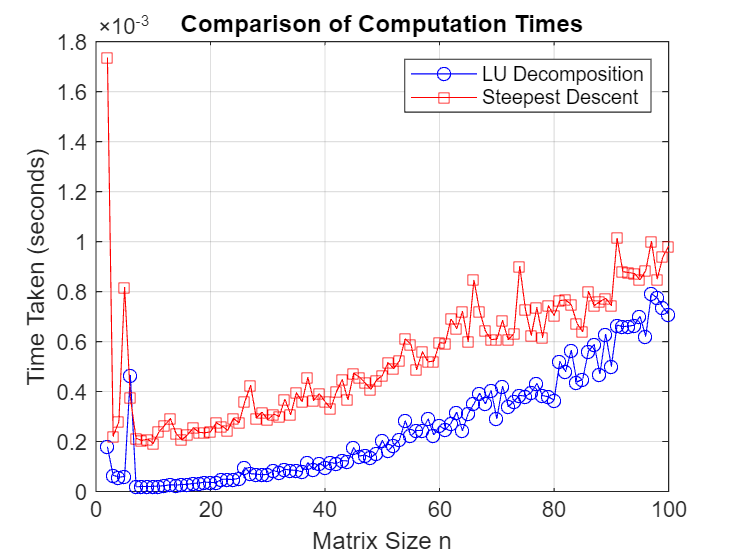

clear all;
lu_times = zeros(99, 1);
sd_times = zeros(99, 1);
sizes = 2:100; 

for n = sizes
    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);

    % Measure time for the pivoted LU decomposition method
    tic;
    [L, U, P] = lu(A); % LU decomposition
    y = L \ ( P * b ); % solve Ly = b
    x_lu = U \ y; % solve Ux = y
    lu_times(n-1) = toc;

    % Measure time for Steepest Descent method
    Xguess = zeros(n, 1); % initial guess for Steepest Descent
    tic;
    [x_sd, ~] = my_steepest_descent(A, b, Xguess, 1e-6, 1000);
    sd_times(n-1) = toc; % store time taken
end

% Plotting the results
figure;
plot(sizes, lu_times, 'b-o', sizes, sd_times, 'r-s');
xlabel('Matrix Size n');
ylabel('Time Taken (seconds)');
title('Comparison of Computation Times');

legend('LU Decomposition', 'Steepest Descent');
grid on;

% Analysis of which method is faster
if mean(lu_times) > mean(sd_times)
    disp('On average, LU Decomposition takes more time than Steepest Descent.');
else

On average, Steepest Descent takes more time than LU Decomposition.


    disp('On average, Steepest Descent takes more time than LU Decomposition.');
end

**d) In this part, part c) is repeated but solving the matrix systems of size ranging from n= 2 to 1000. Similar to part c, the time taken by LU decomposition based solver and the steepest descent for each matrix size is plotted. On a seperate plot, the number of iterations taken by steepest decent vs matrix size is additionally graphed. A comparison of the plots from part c) and part d) is provided below, along with an analysis of which method takes more time to compute the solution? (5 marks)**

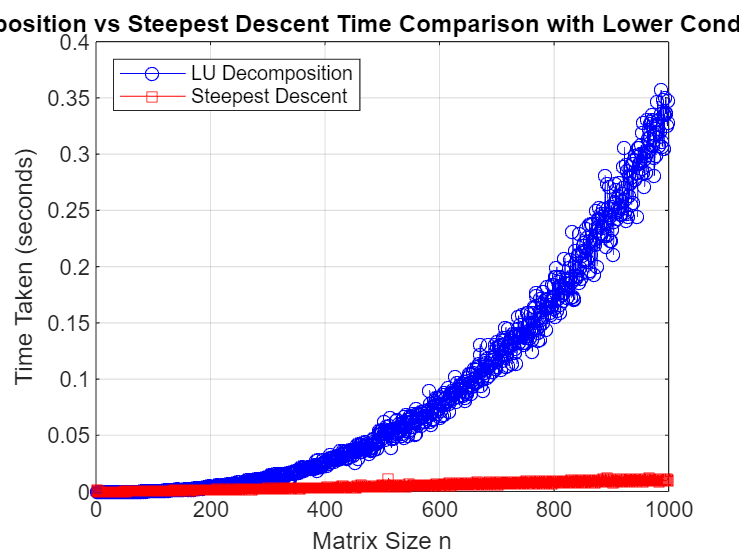

clear all;
lu_times_lower = zeros(999, 1);
sd_times_lower = zeros(999, 1);
sd_iterations_lower = zeros(999, 1);
sizes = 2:1000;

for n = sizes
    [A, b] = getSystemMatrix_with_lowerConditionNumber(n);

    % Measure time for the pivoted LU decomposition method
    tic;
    [L, U, P] = lu(A); % LU decomposition
    y = L \ ( P * b ); % solve Ly = b
    x_lu = U \ y; % solve Ux = y
    lu_times_lower(n-1) = toc; 

    % Measure time for Steepest Descent method
    Xguess = zeros(n, 1); % Initial guess for Steepest Descent
    tic;
    [x_sd, iter] = my_steepest_descent(A, b, Xguess, 1e-6, 10000); % increase max iterations for larger n
    sd_times_lower(n-1) = toc; % store time taken
    sd_iterations_lower(n-1) = iter; % store iterations taken
end

% Plotting the computation times for higher condition number
figure;
plot(sizes, lu_times_lower, 'b-o', sizes, sd_times_lower, 'r-s');
xlabel('Matrix Size n');
ylabel('Time Taken (seconds)');
title('LU Decomposition vs Steepest Descent Time Comparison with Lower Condition Number');

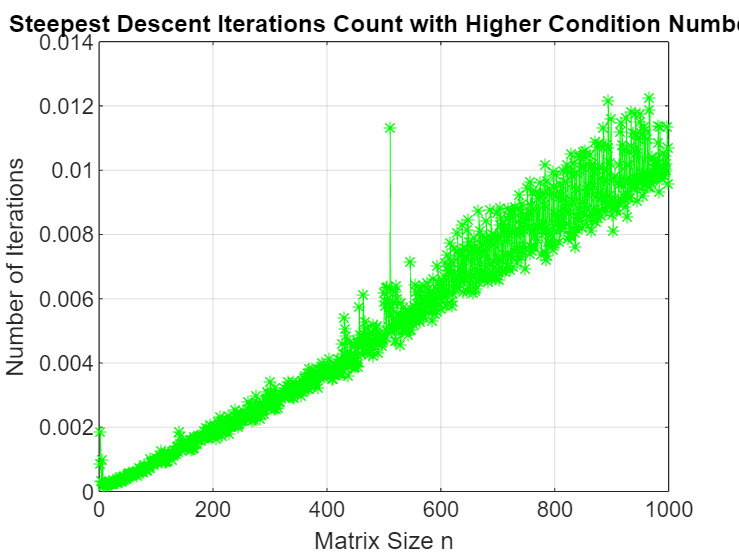

legend('LU Decomposition', 'Steepest Descent', 'Location', 'northwest');
grid on;

% Plotting the iterations for Steepest Descent with higher condition number
figure;
plot(sizes, sd_times_lower, 'g-*');
xlabel('Matrix Size n');
ylabel('Number of Iterations');

title('Steepest Descent Iterations Count with Higher Condition Number');
grid on;
% Analysis of which method is faster
if mean(lu_times_lower) > mean(sd_times_lower)
    disp('On average, LU Decomposition takes more time than Steepest Descent.');
else

On average, LU Decomposition takes more time than Steepest Descent.


    disp('On average, Steepest Descent takes more time than LU Decomposition.');
end

*For well-conditioned matrices, the Steepest Descent algorithm can perform quite efficiently and converges to the accurate solution in fewer iterations. The path to the minimum is more direct, and the numerical stability is higher, making the Steepest Descent a viable option for well-conditioned matrices, especially when the matrix size is quite large. Upon analyzing the plot, it is evident that LU decomposition outpaces the Steepest Descent method in solving systems with smaller matrices. However, as the matrix size increases, LU Decomposition becomes less efficient in comparison to Steepest Descent. This shift in performance can primarily be attributed to the substantial computational effort required for constructing the LU decomposition of larger matrices. The process of decomposing a matrix into lower and upper triangular matrices (LU Decomposition) demands a significant amount of calculations, which increases with the size of the matrix. Consequently, for larger matrices, this decomposition phase dominates the total computation time. In contrast, the iterative nature of the Steepest Descent method, which does not necessitate an upfront decomposition, becomes relatively more time-efficient as the matrix size grows. This method incrementally approaches the solution, making it better suited for larger matrices where the overhead of LU Decomposition becomes a critical factor.*

**e)** **Similar to the previous part*****, *****the matrix systems of sizes ranging from n = 2 to 1000 are solved. The function *****getSystemMatrix_with_higherConditionNumber *****is used to generate the system matrix** $\textbf A$*** and vector ***$\textbf b$***. *****The function, *****getSystemMatrix_with_higherConditionNumber, ***** generates the system matrix **$\textbf A$** with a slightly higher condition number than the matrix you used in parts c) and d). The time taken by LU decomposition based solver and the steepest descent algorithm vs. matrix size is plotted below. A comment on the similarities and differences between the plots from part d) and e) is provided below.  (5 marks)**

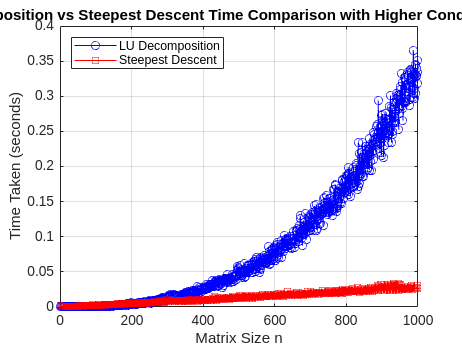

clear all;
lu_times_higher = zeros(999, 1);
sd_times_higher = zeros(999, 1);
sd_iterations_higher = zeros(999, 1);
sizes = 2:1000;

for n = sizes
    [A, b] = getSystemMatrix_with_higherConditionNumber(n);

    % Measure time for the pivoted LU decomposition method
    tic;
    [L, U, P] = lu(A); % LU decomposition
    y = L \ ( P * b ); % solve Ly = b
    x_lu = U \ y; % solve Ux = y
    lu_times_higher(n-1) = toc; 

    % Measure time for Steepest Descent method
    Xguess = zeros(n, 1); % Initial guess for Steepest Descent
    tic;
    [x_sd, iter] = my_steepest_descent(A, b, Xguess, 1e-6, 10000); % increase max iterations for larger n
    sd_times_higher(n-1) = toc; % store time taken
    sd_iterations_higher(n-1) = iter; % store iterations taken
end

% Plotting the computation times for higher condition number
figure;
plot(sizes, lu_times_higher, 'b-o', sizes, sd_times_higher, 'r-s');
xlabel('Matrix Size n');
ylabel('Time Taken (seconds)');
title('LU Decomposition vs Steepest Descent Time Comparison with Higher Condition Number');

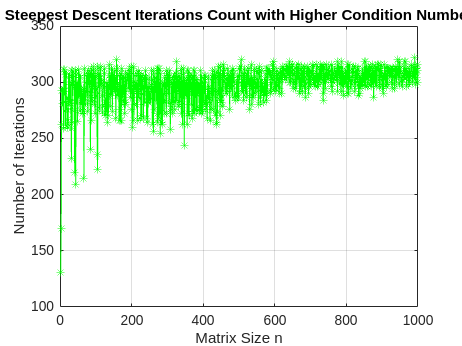

legend('LU Decomposition', 'Steepest Descent', 'Location', 'northwest');
grid on;
% Plotting the iterations for Steepest Descent with higher condition number
figure;
plot(sizes, sd_iterations_higher, 'g-*');
xlabel('Matrix Size n');
ylabel('Number of Iterations');

title('Steepest Descent Iterations Count with Higher Condition Number');
grid on;

*Similar to the results in part d), the Steepest Descent algorithm is slower than LU Decomposition for smaller matrix sizes but for largest matrix sizes Steepest Descent is faster at finding the solution. The main difference is that for an ill-conditioned matrix, the presence of a high condition number means that the solution is prone to potential numerical instabilities and a significantly increased number of iterations is required for convergence. The direction of steepest descent may not point towards the solution as directly as it would with well-conditioned matrices, making the convergence slow and sometimes even impractical due to rounding errors and accumulation of numerical inaccuracies. For LU Decomposition, while it can still be applied to ill-conditioned matrices, the solution obtained may suffer from numerical instability and rounding errors. Overall, for a higher condition number, the Steepest Descent algorithm still outperforms LU Decomposition for larger matrix sizes but takes a significant amount of iterations to reach convergene. As a result, the time taken for each algorithm also increases. *

**Sources used to complete this section:**

- [Iterative methods to solve linear systems, steepest descent (mit.edu)](https://ocw.mit.edu/courses/18-409-topics-in-theoretical-computer-science-an-algorithmists-toolkit-fall-2009/68f1b1ba4d419ee8f3b67a41ebf258e8_MIT18_409F09_scribe21.pdf)

## Appendix 

function [A,b]= getSystemMatrix_with_lowerConditionNumber(n)
    % inputs: n is the size of the matrix
    %
    % outputs: A square matrix of size n times n
    %          b  vector of size n.

    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.25);
    A= R'*R;
    b = rand(n,1);
end

function [A,b]= getSystemMatrix_with_higherConditionNumber(n)
    % inputs: n is the size of the matrix
    %
    % outputs: A square matrix of size n times n
    %          b  vector of size n.

    rng(0);
    density =10/n;
    R = sprand(n,n,density,0.15);
    A= R'*R;
    b = rand(n,1);
end

function [x, iter] = my_steepest_descent(A, b, Xguess, tol, maxiter)
    % inputs: A is a symmeteric and positiv definite matrix.
    %         b is an RHS vector
    %         Xguess is the initial guess 
    %         tol is the tolerance 
    %         maxiter is the maximum iterations 
    %
    % outputs: x is the solution of the system Ax = b
    %          iter is the number of iterations it took to converge
    
    iter = 0;
    x = Xguess;
    error = norm(A*x-b);

    while iter < maxiter && error > tol
        r = b - A * x;
        alpha = (r.'*r)/(r.'*A*r);
        x = x + alpha*r;
        error = norm(A*x-b);
        iter = iter + 1;
    end
end